# Voronoi Diagram example

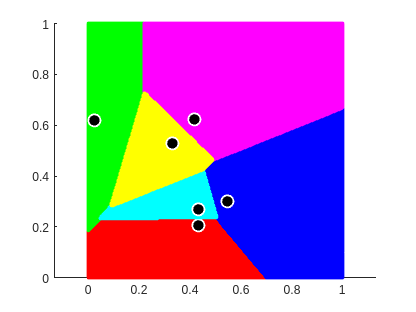

rng(2)
X = rand([6,1]);
Y = rand([6,1]);
XY = [X Y];

% Define group labels
group = [1 2 3 4 5 6]';

% Define custom color map for your groups
color_map = [1 0 0; % red
             0 1 0; % green
             0 0 1; % blue
             0 1 1; % cyan
             1 0 1; % magenta
             1 1 0]; % yellow

% Create grid
[x, y] = meshgrid(0:0.001:1, 0:0.001:1);
grid_points = [x(:), y(:)];

% Calculate the distance between grid points and original points
distances = pdist2(grid_points, XY);

% Find the closest original point for each grid point
[~, closest_points] = min(distances, [], 2);

% Plot Voronoi diagram using the grid and closest point information
figure;
hold on;

for i = 1:length(group)
    % Plot grid points belonging to the current region
    scatter(grid_points(closest_points == i, 1), grid_points(closest_points == i, 2), 10, color_map(i, :), 'filled', 'MarkerEdgeColor', 'none');
    
    % Plot original points on top of the grid
    scatter(XY(i, 1), XY(i, 2), 100, 'k', 'o', 'filled', 'MarkerEdgeColor', 'w', 'LineWidth', 1.5);
end

hold off;
axis equal;